# Final Project

First, set the given parameters as methods of parameter, so that they can be called in the function as one variable.

clear;
clc;
clf;

parameter.m = 0.3;
parameter.I = 1/12;
parameter.L = 0.5;
parameter.r = 0.1;
parameter.g = 9.8;

parameter.desiredtheta = 0;

Set the time with equal splits of 1000 from 0 to 20. Then set the initial conditions (theta,dtheta, and ddtheta). Set those equal to an array that will be called by our function. Set the sensitivity of ODE45. Pass the paramters and the function through ODE45 so that theta (and the other variables) can be solved for. 

t = 20;
time = linspace(0,t,1000)';

theta0 = -45;
dtheta = 0;
inttheta = 0;

statevar0 = [theta0; dtheta; inttheta];

sens = odeset('reltol',1e-9,'AbsTol',1e-9);

[tlist,statevarlist] = ode45(@PID,time,statevar0,sens,parameter);

thetalist = statevarlist(:,1); %column1
velocitylist = statevarlist(:,2); %column2

Create a for loop to animate the arm moving. The arm's path is beign dictated by thetalist, which is the list of theta values that was calculated by ODE45.

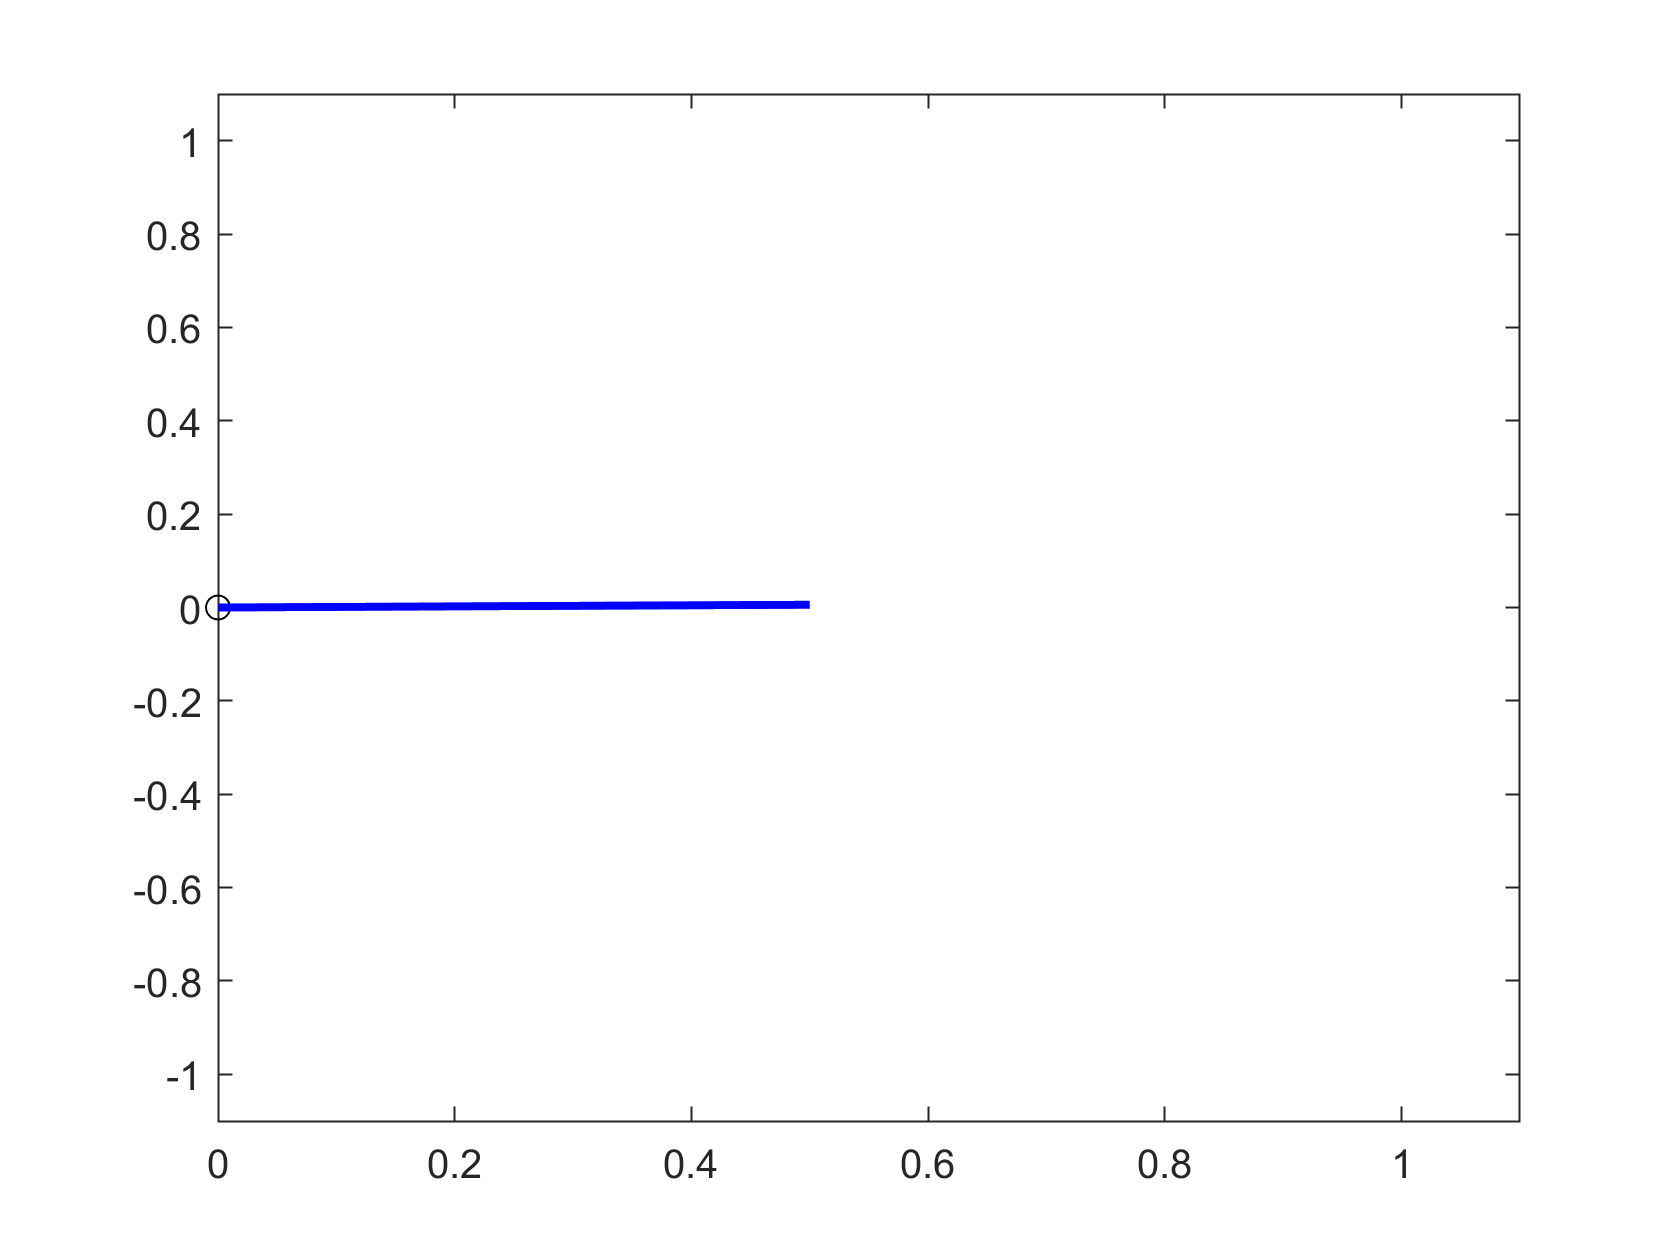

for i = 1:10:length(thetalist)
    
    x = 0.5*cosd(thetalist(i));
    y = 0.5*sind(thetalist(i));

    plot(0,0,'ko')
    hold on
    plot([0 x],[0 y],'b','LineWidth',2);
    axis([0 1.10 -1.10 1.10])
    hold off
    pause(0.00005)
end

Plot theta by time and velocity by time.

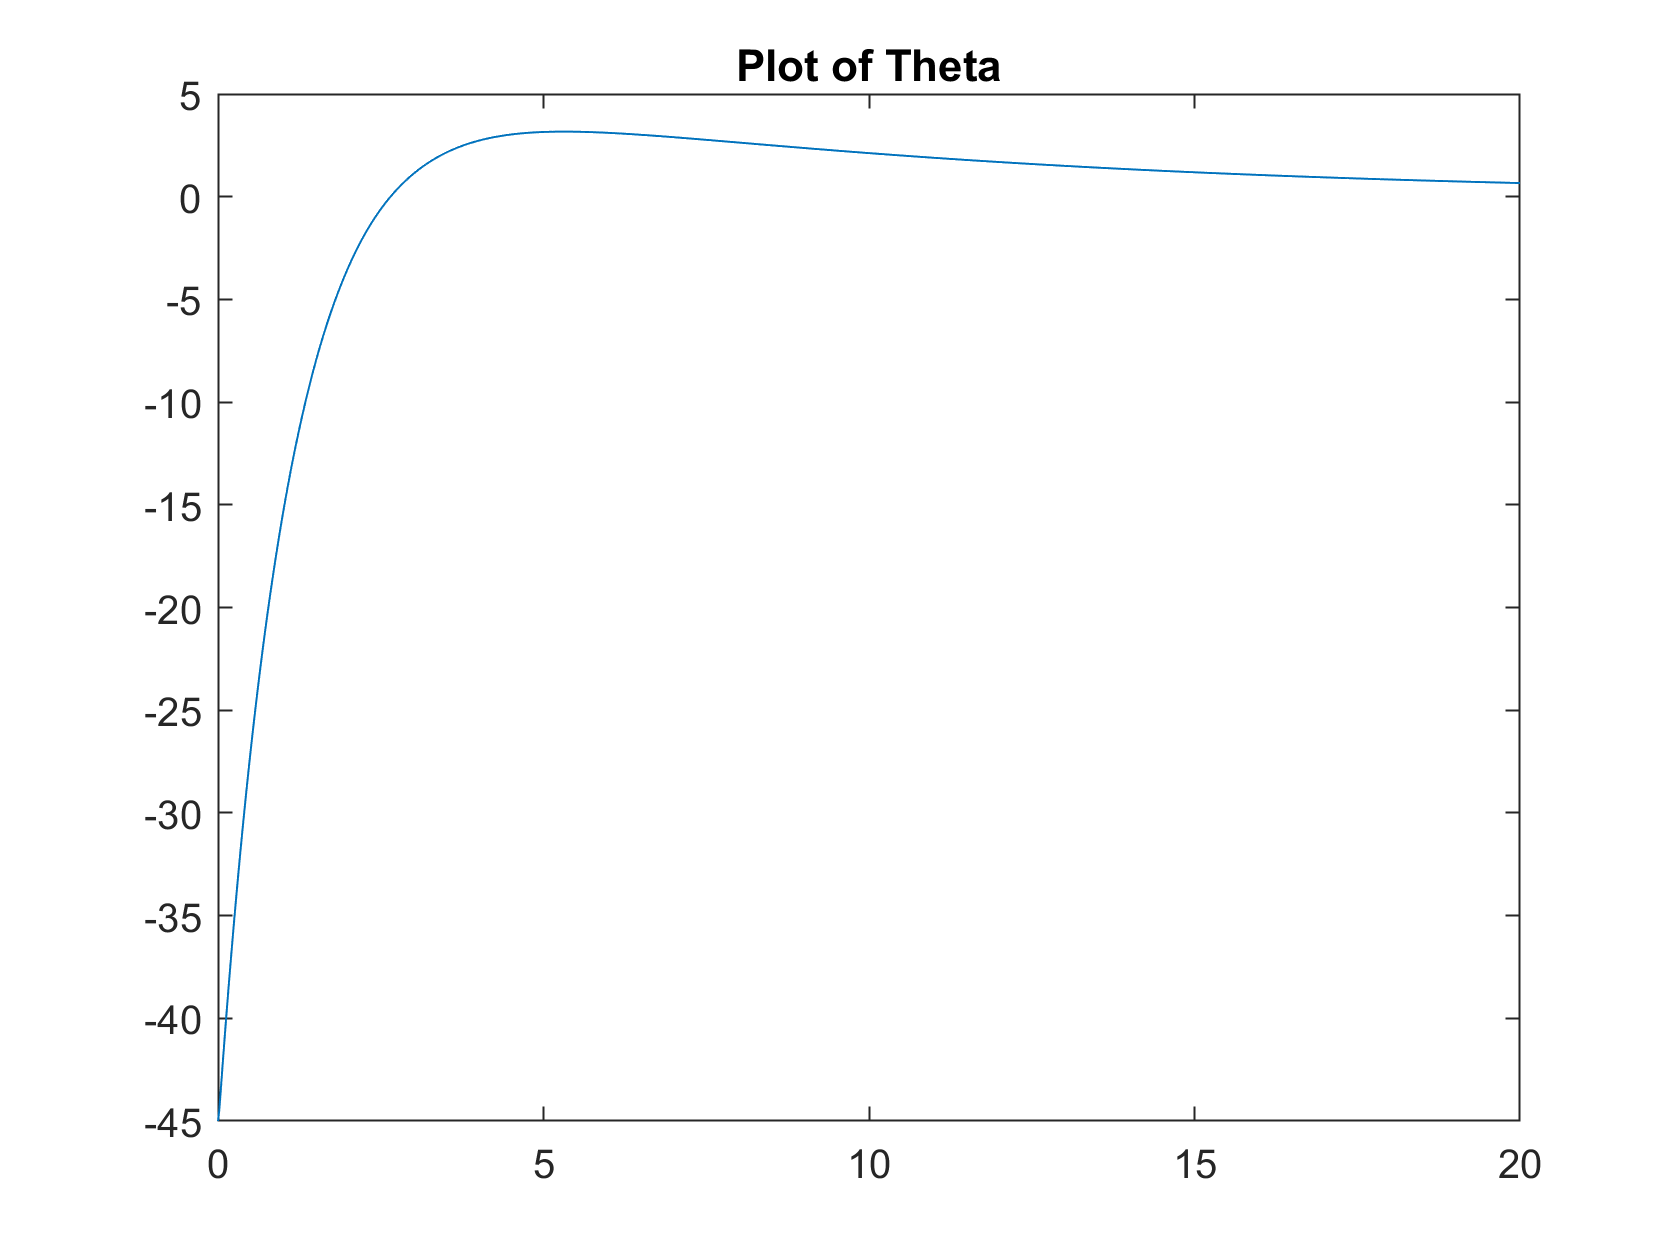

figure (2)
plot(time,thetalist,'-')
title("Plot of Theta")

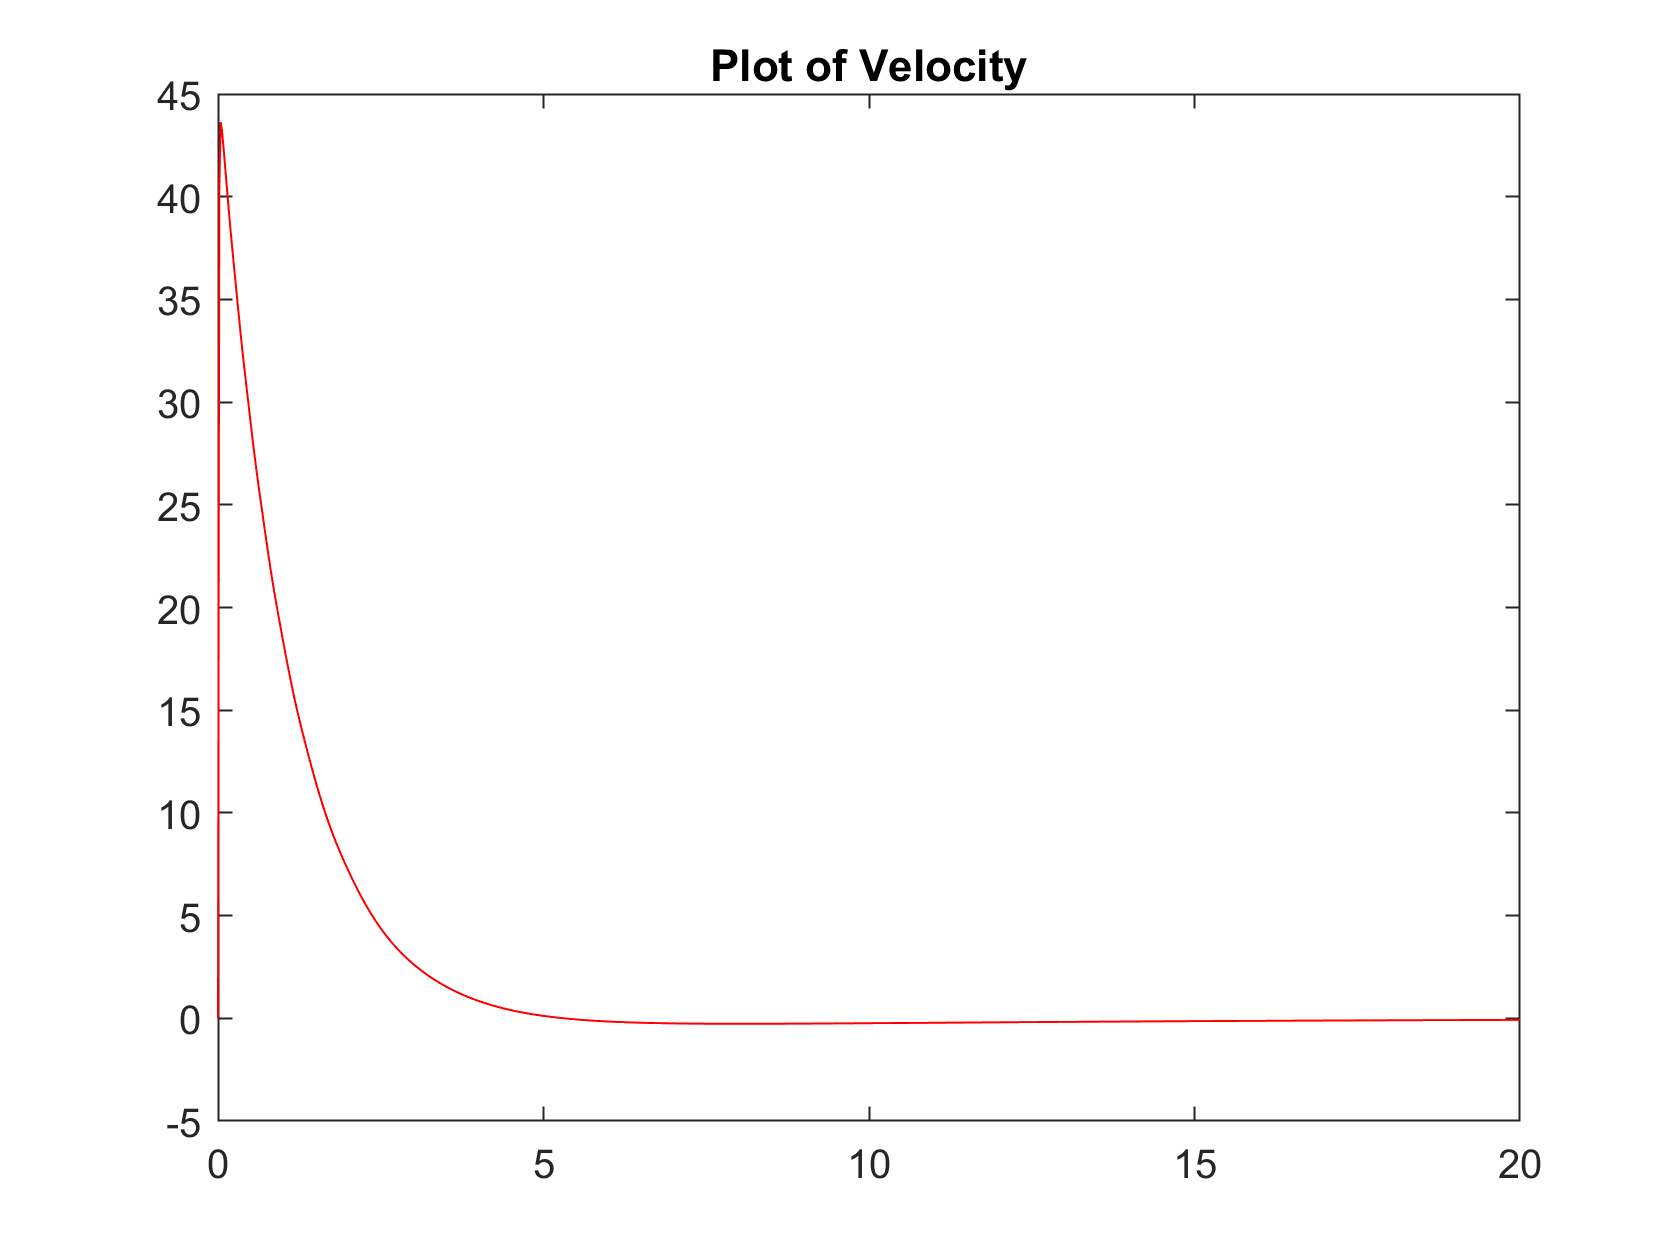


figure(3)
plot(time,velocitylist,'r-')
title("Plot of Velocity")

# PD Controller

The process is the same as the PID controller except it's control law will not have the integral part.

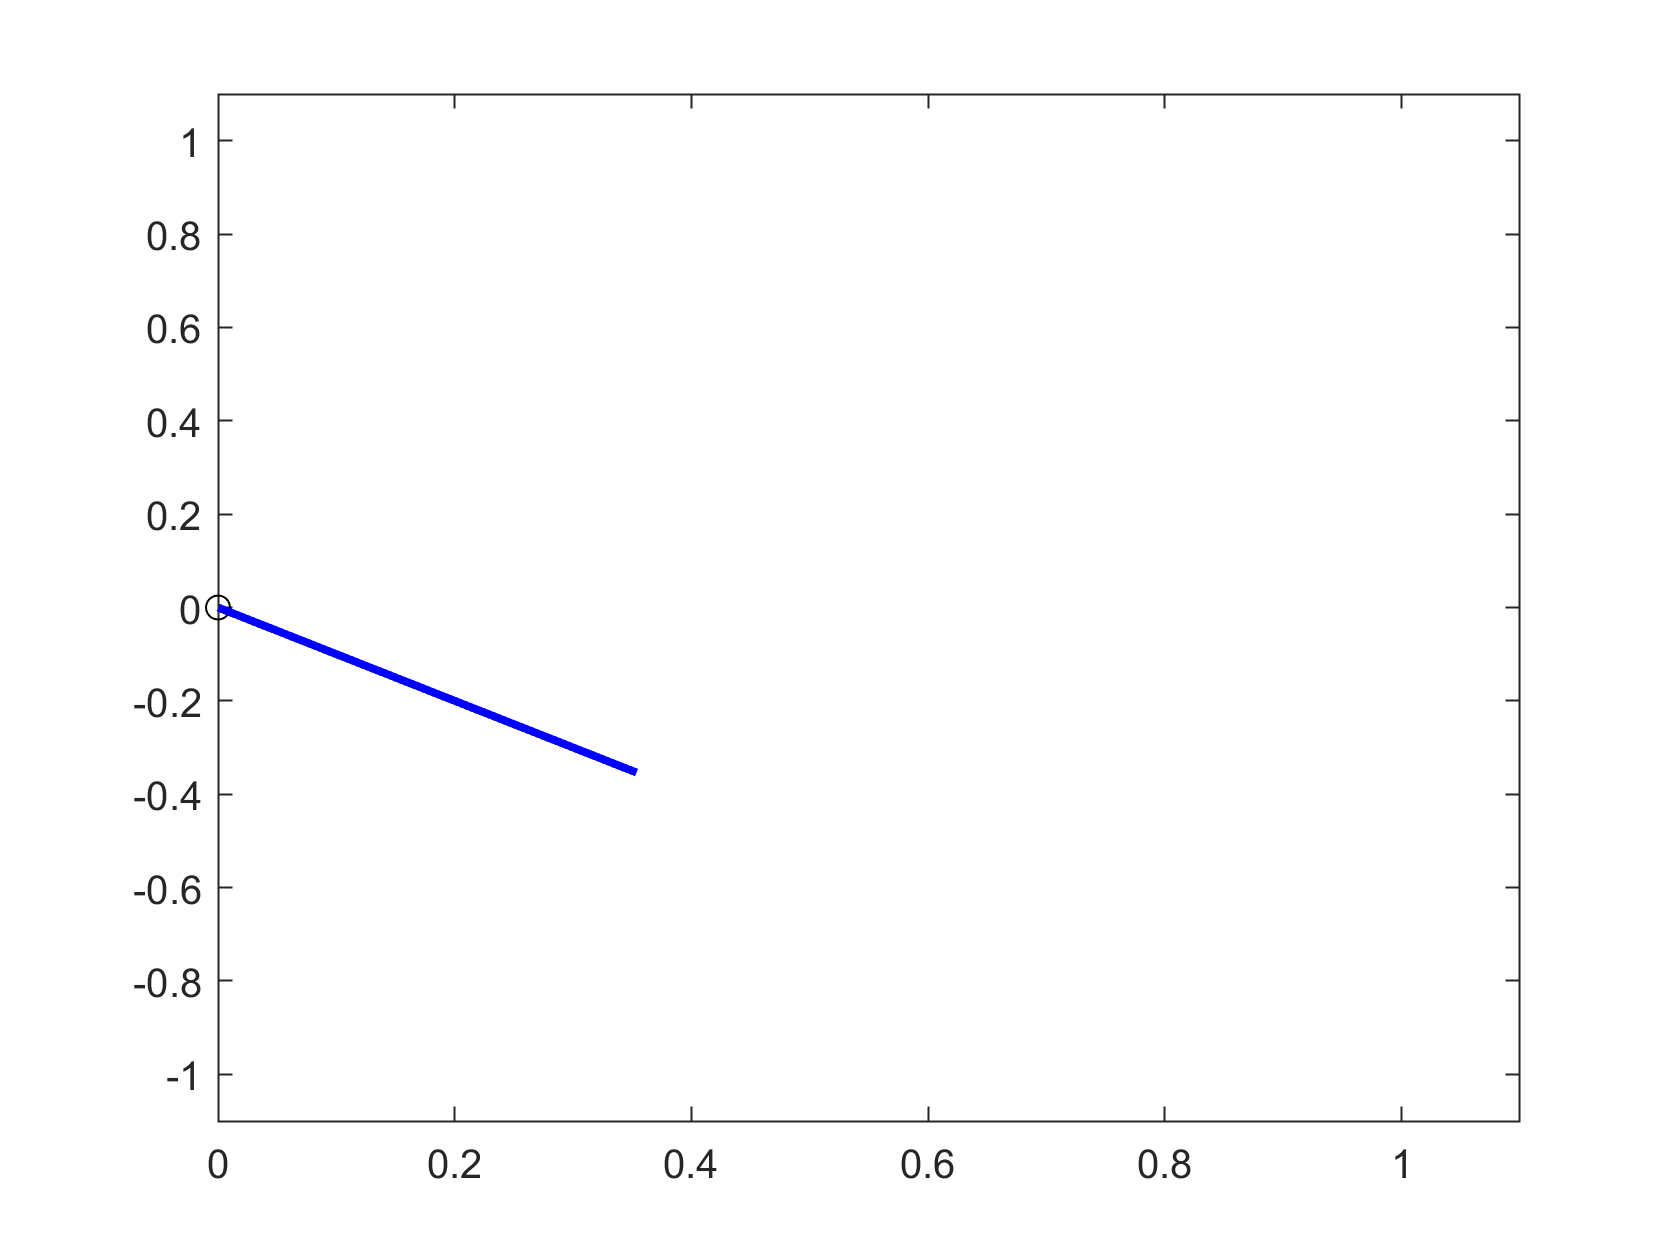

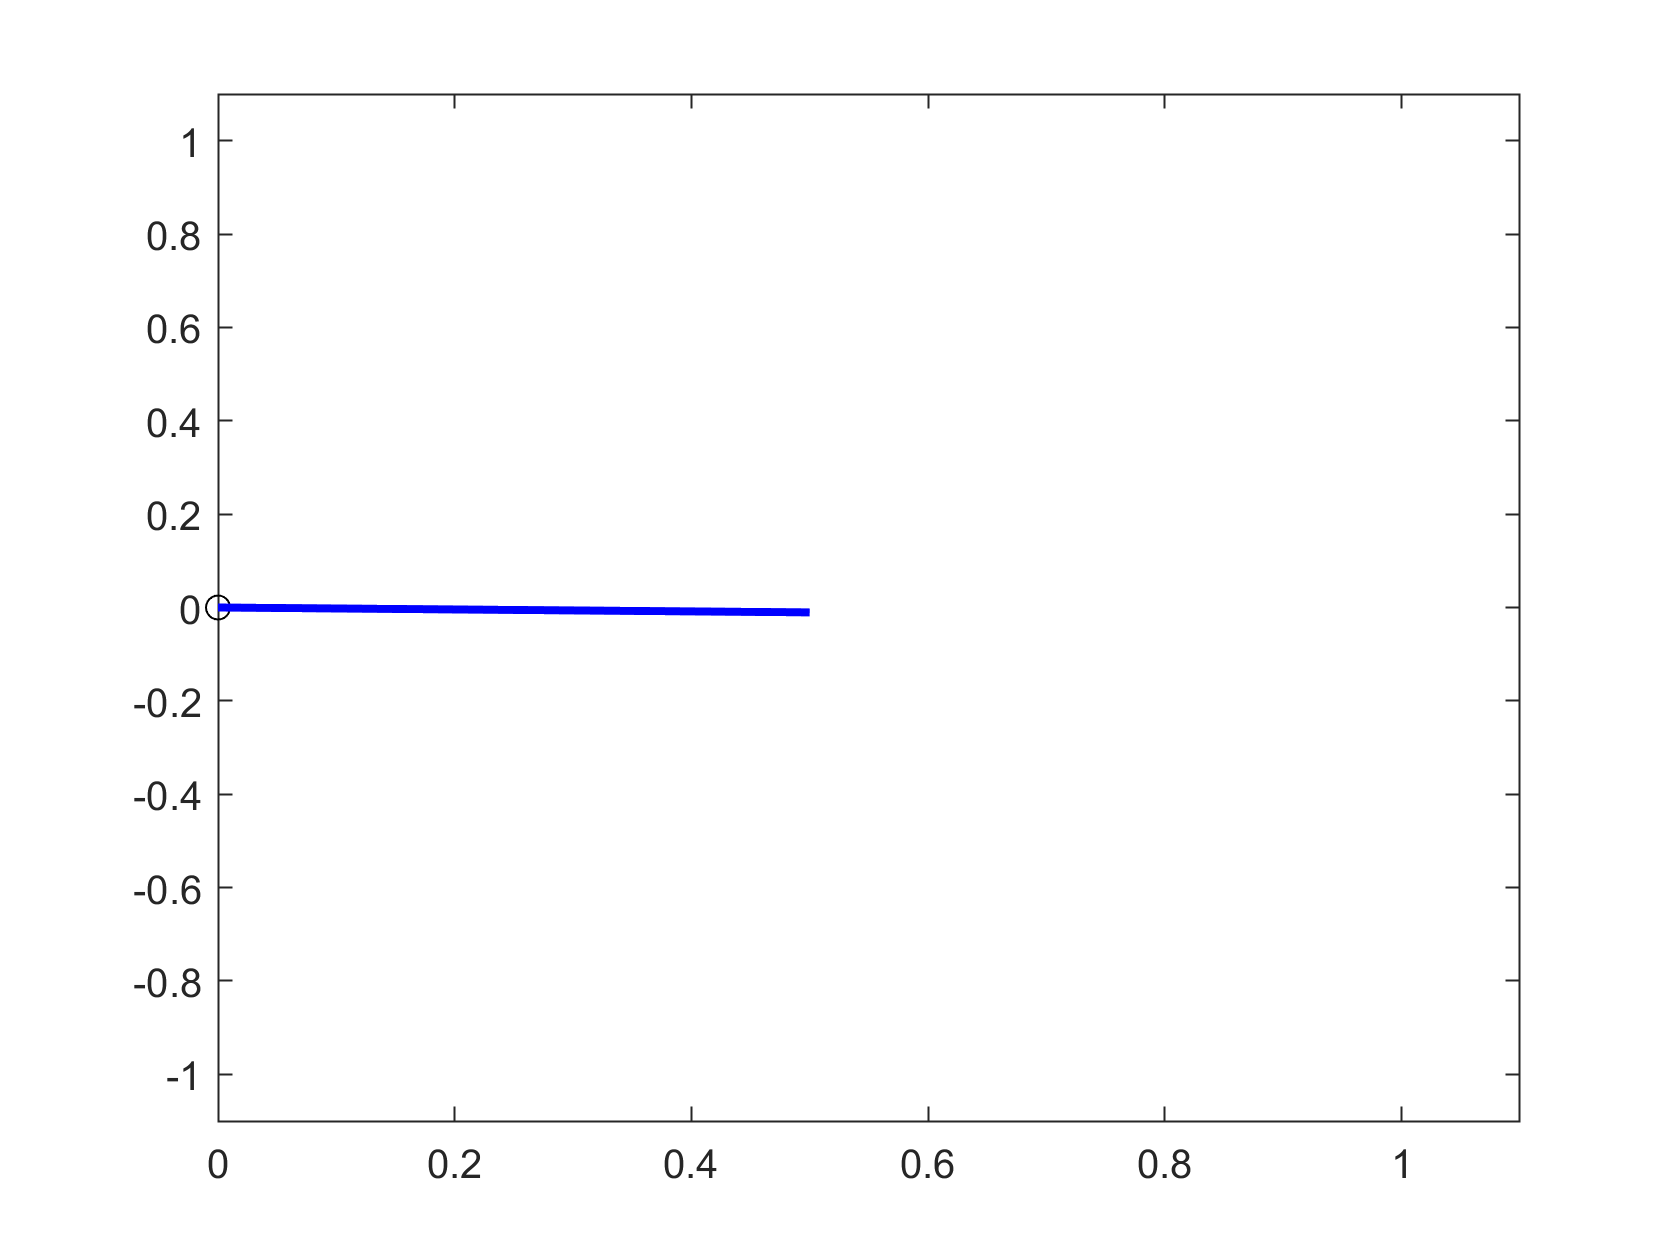

clear;
clc;
clf;

parameter.m = 0.3;
parameter.I = 1/12;
parameter.L = 0.5;
parameter.r = 0.1;
parameter.g = 9.8;

parameter.desiredtheta = 0;

t = 20;
time = linspace(0,t,1000)';

theta0 = -45;
dtheta = 0;
int = 0;
statevar0 = [theta0; dtheta];

sens = odeset('reltol',1e-3,'AbsTol',1e-3);

[tlistPD,statevarlistPD] = ode45(@PD,time,statevar0,sens,parameter);

thetalistPD = statevarlistPD(:,1); %column1
velocitylistPD = statevarlistPD(:,2); %column2

for i = 1:10:length(thetalistPD)
    
    xPD = 0.5*cosd(thetalistPD(i));
    yPD = 0.5*sind(thetalistPD(i));

    plot(0,0,'ko')
    hold on
    plot([0 xPD],[0 yPD],'b','LineWidth',2);
    axis([0 1.10 -1.10 1.10])
    hold off
    pause(0.00005)
    
    %F(i) = getframe(gcf);
end


%newVid1 = VideoWriter('PD Movie.mp4', 'MPEG-4');
%open(newVid1);
%writeVideo(newVid1,F);
%close(newVid1);

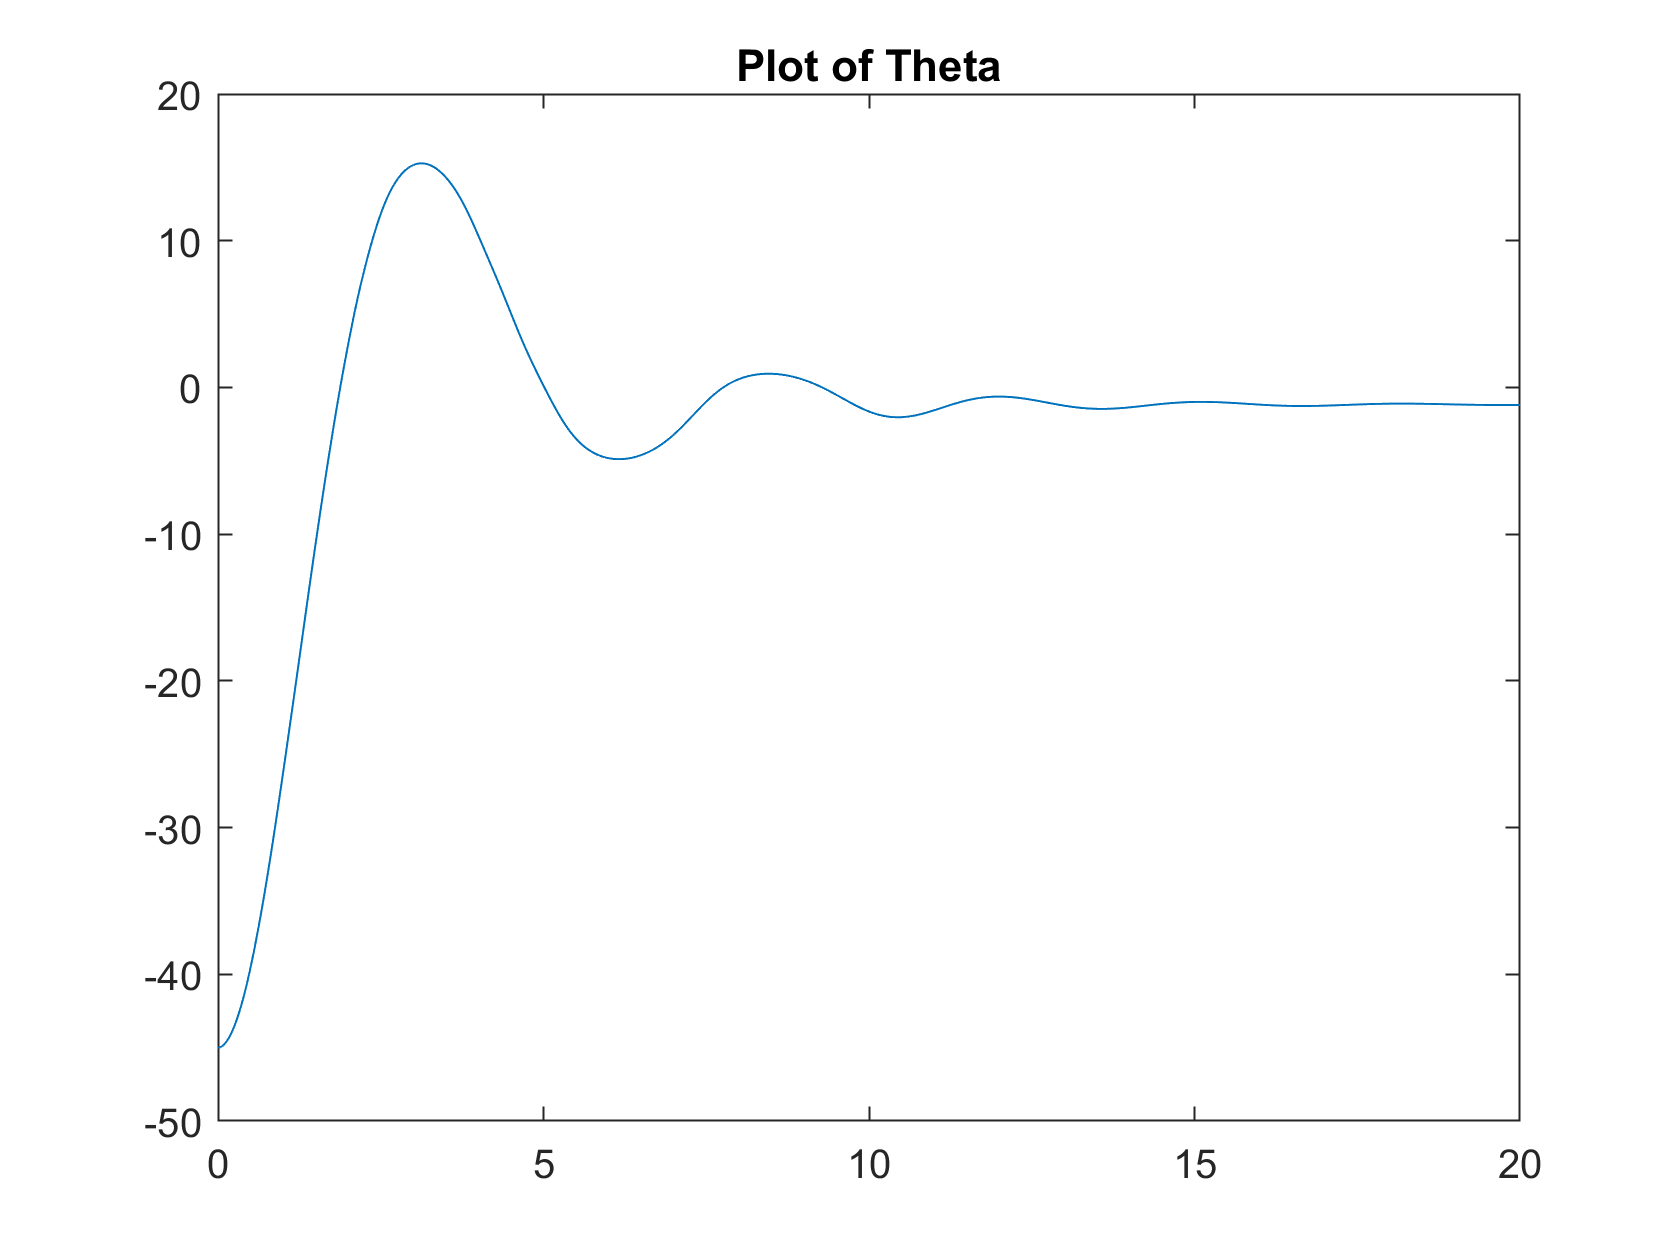

figure (2)
plot(time,thetalistPD,'-')
title('Plot of Theta')

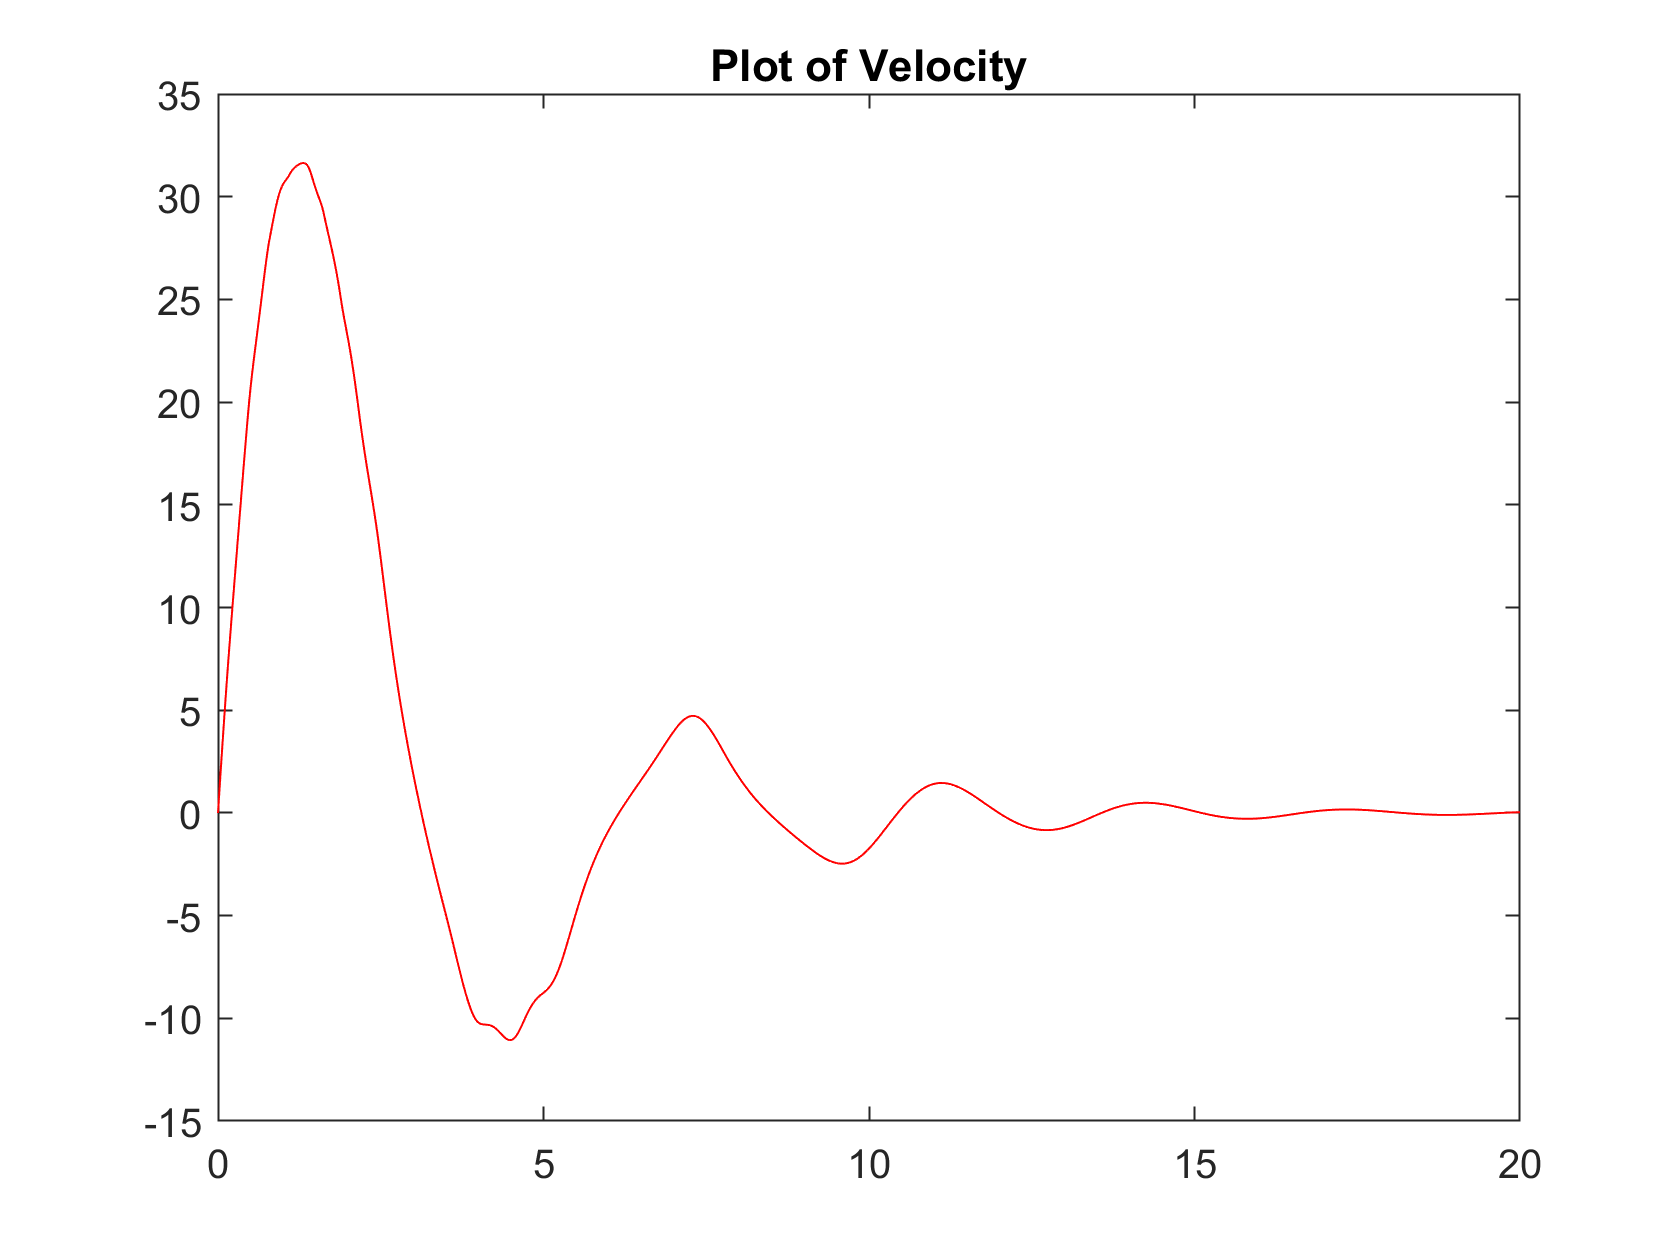


figure(3)
plot(time,velocitylistPD,'r-')
title('Plot of Velocity')

## Thoughts

The PD controller does not require high values of kp and kv. The values were .1 and 0.6 and they were not even completely finely tuned. It really depends on the application for which one is better because the PID can get exactly to the point quicker but the PD controller overshoots and gets nearer to the specified value quicker. With more tuning I may have been able to get the PD controller to steady state quicker, but I believe that the PID controller would still reach the steady state sooner than the PD controller. The PD controller would oscillate very near zero, but would not reach there perfectly.

# Sources

The example Dr. Z showed in class helped witht the foundation of my project, so I am citing the final project video as inspiration.

function dstatevar = PD(t,statevar,parameter)
    theta = statevar(1);
    dtheta = statevar(2);
    
    m = parameter.m;
    I = parameter.I;
    L = parameter.L;
    r = parameter.r;
    g = parameter.g;
    desire = parameter.desiredtheta;
    
    kp = .1;
    kv = .06;
    
    tau = -kp*(theta-desire)-kv*dtheta;
    
    dstatevar = [dtheta; (-g*m*r*cos(theta)+tau)/(m*r^2+I)];
end



function dstatevar = PID(t,statevar,parameter)
    theta = statevar(1);
    dtheta = statevar(2);
    y = statevar(3);

    m = parameter.m;
    I = parameter.I;
    L = parameter.L;
    r = parameter.r;
    g = parameter.g;
    desire = parameter.desiredtheta;

    kp = 10;
    kv = 10;
    ki = 1;

    tau = -kp*(theta-desire)-kv*dtheta-ki*y;

    dstatevar = [dtheta; (-g*m*r*cos(theta)+tau)/(m*r^2+I); theta-desire];
end